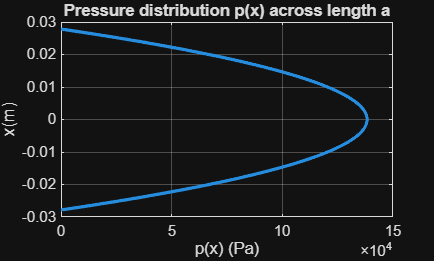

% https://mydailyengineering.wordpress.com/dry-steering/
% bilder av cad ligger i https://drive.google.com/drive/u/1/folders/1R42UJ85xGUDm-tD5RUjfcWQPFO0rt5rP
clc; clear; close all;

a_mm = 55.67; % mm kort side kontaktflate
b_mm = 154; % mm Langside kontaktflate
Fz_kg = 80.575; % kg vekt på hjulet
sigma_deg = 7.98; % deg KPI
tau_deg = 6.18; % deg caster
r_dyn_mm = 203.2; % mm radius hjul hjul
CD_mm = 28.48; % mm   r_dyn * tan sigma
rs_mm = 10.05; % mm  skrubb radie, DO linja
delta_deg = linspace(-31, 31, 1000);   % deg styrevinkel
delta_deg2 = linspace(0,31,1000);

g = 9.81;         % m/s^2
a = a_mm*1e-3;    % m  
b = b_mm*1e-3;    % m
Fz = Fz_kg*g;      % N
x = linspace(-a/2, a/2, 1000);   % m
sigma = deg2rad(sigma_deg); % rad
tau = deg2rad(tau_deg); % rad
r_dyn = r_dyn_mm*1e-3; % m
CD = CD_mm*1e-3; % m
rs = rs_mm*1e-3; % m
delta = deg2rad(delta_deg); % rad

% Pressure Distribution
p = (6*Fz/(a^3*b)) .* (a/2 - x) .* (a/2 + x);  % Pa (N/m^2)

plot(p, x, 'LineWidth', 2)
grid on
xlabel('p(x) (Pa)')
ylabel('x(m)')
title('Pressure distribution p(x) across length a')

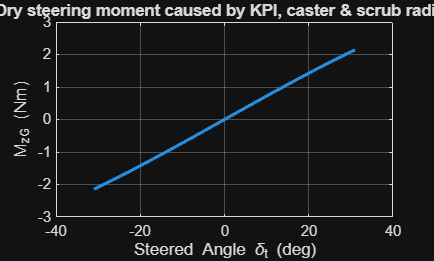


% Gravity based aligning moment
MzG = Fz * (rs + r_dyn*tan(sigma)) .* cos(sigma) .* sin(sigma) .* cos(tau) .* sin(delta); % Nm

figure
plot(delta_deg, MzG, 'LineWidth', 2)
grid on
xlabel('Steered Angle \delta_t (deg)')
ylabel('M_{zG} (Nm)')
title('Dry steering moment caused by KPI, caster & scrub radius')


% Friction based moment
x0 = -a/2;
x1 = a/2;
y0 = -b/2; 
y1 = b/2; 

e0 = 24.03e-3; %m
beta = 10; %degrees

ex = e0*cosd(beta);
ey = e0*sind(beta);
mu = 1.75; %friction coeff

fun = @(x,y) ((6*Fz)/(a^3*b) .* (a/2 - x) .* (a/2 + x)).*(sqrt((ex - x).^2 + (ey - y).^2));

Mzft = mu * integral2(fun, x0, x1, y0, y1);

Mzf = Mzft*cos(sigma)*cos(tau); %Nm
%Mzf = Mzf/1000; %Nm
Mfo = 0.4; %Nm
D = 47.5e-3; %m

Lk = 84.55e-3; %m
theta_tk = linspace(107.55, 84.17,1000); %degrees
theta_tk = deg2rad(theta_tk);
theta_rt = linspace(179.95,179.59,1000); %degrees
theta_rt = deg2rad(theta_rt);
theta_kk = deg2rad(68.54); %degrees
Frt = 1; %N ÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆ
R = D/2; %m
L = Lk .* sin(theta_tk);
Ftt = Frt .* cos(pi-theta_rt);
i = (Ftt .* L .* cos(theta_kk-(pi/2)))/(Frt .* R);

Mz = 2*((Mzf+MzG)./i) + Mfo

Mz =    40.6822   40.6794   40.6767   40.6740   40.6712   40.6685   40.6658   40.6631   40.6604   40.6578   40.6551   40.6524   40.6498   40.6471   40.6445   40.6419   40.6392   40.6366   40.6340   40.6315   40.6289   40.6263   40.6237   40.6212   40.6186   40.6161   40.6136   40.6110   40.6085   40.6060   40.6035   40.6011   40.5986   40.5961   40.5937   40.5912   40.5888   40.5863   40.5839   40.5815   40.5791   40.5767   40.5743   40.5719   40.5696   40.5672   40.5649   40.5625   40.5602   40.5579


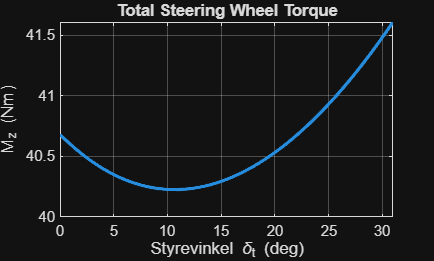

figure
plot(delta_deg2, Mz, 'LineWidth', 2)
grid on
xlabel('Styrevinkel \delta_t (deg)')
ylabel('M_{z} (Nm)')
title('Total Steering Wheel Torque')